rg = 0.0254;
L = 0.4255;
g = 9.81;
K = 1.5;
tau = 0.025;

dt = 0.01

dt = 0.0100

numSteps = 1000;
T_total = numSteps * dt;

initialState = [0.1; 0.3; 90; 0.25];

% Get a numerical solution of the ODE model to compare against
odeFcn = @(t, x) ballbeam_ODE(t, x, g, L, rg, tau, K);
[t_cont, x_cont] = ode45(odeFcn, [0 T_total], initialState);

% Discretize f 
discrete_f = @(x, u) x + dt * [ x(2); ((5 * g * rg)/(7 * L)) * sin(x(3)) - (5/7) * ((L/2) - x(1)) * ((rg/L) * x(4))^2 * cos(x(3))^2;
    x(4); -1 * x(4)/tau + (K/tau) * u ];

syms x1 x2 x3 x4 u_sym dt_sym real

x_sym = [x1; x2; x3; x4];

% Make it symbolic 
f1_sym = x1 + dt_sym * x2;
f2_sym = x2 + dt_sym * (((5 * g * rg)/(7 * L)) * sin(x3) - (5/7) * ((L/2) - x1) * ((rg/L) * x4)^2 * cos(x3)^2);
f3_sym = x3 + dt_sym * x4;
f4_sym = x4 + dt_sym * (-1 * x4/tau + (K/tau) * u_sym);
f_sym = [f1_sym; f2_sym; f3_sym; f4_sym];

J_sym = jacobian(f_sym, x_sym);

% Convert the symbolic Jacobian into a MATLAB function handle.
% It will depend on the state vector x, control input u, and dt.
J_handle = matlabFunction(J_sym, 'Vars', {[x1; x2; x3; x4], u_sym, dt_sym});

% Fix dt. 
f_Jacobian = @(x, u) J_handle(x, u, dt);

measurement_z = @(x) [x(1); x(3)];

z_Jacobian = @(x) [1 0 0 0; 0 0 1 0];

ekf = extendedKalmanFilter(discrete_f, measurement_z, initialState, ...
    'StateTransitionJacobianFcn', f_Jacobian, ...
    'MeasurementJacobianFcn', z_Jacobian);

% Can tune these as needed. 
ekf.ProcessNoise = diag([1e-5, 1e-4, 1e-4, 1e-5]);
ekf.MeasurementNoise = diag([1e-4, 1e-4]);

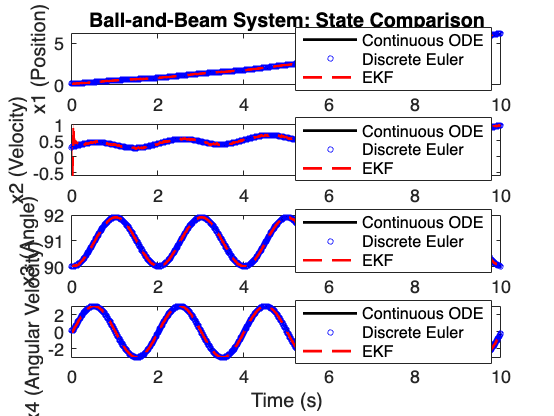

trueState = initialState;
trueStateHistoryDiscrete = zeros(4, numSteps);
ekfStateHistory = zeros(4, numSteps);
timeHistory = (0:numSteps - 1) * dt;

for k = 1 : numSteps
    t = (k - 1) * dt;
    
    % Sinusoidal control input: e.g., 0.5 Hz frequency, amplitude 0.5
    u = 2 * sin(2 * pi * 0.5 * t);
    
    trueState = discrete_f(trueState, u);
    trueStateHistoryDiscrete(:, k) = trueState;
    
    % Generate a noisy measurement
    zTrue = measurement_z(trueState);
    z = zTrue + chol(ekf.MeasurementNoise)' * randn(2,1);
    
    % Run EKF predict and correct steps
    predict(ekf, u);
    ekfState = correct(ekf, z);
    ekfStateHistory(:, k) = ekfState;
end

figure;

% Plot Ball Position (x1)
subplot(4,1,1);
plot(t_cont, x_cont(:,1), 'k-', 'LineWidth', 1.5); hold on;
plot(timeHistory, trueStateHistoryDiscrete(1,:), 'bo', 'MarkerSize', 3);
plot(timeHistory, ekfStateHistory(1,:), 'r--', 'LineWidth', 1.5);
ylabel('x1 (Position)');
legend('Continuous ODE','Discrete Euler','EKF','Location','best');
title('Ball-and-Beam System: State Comparison');

% Plot Ball Velocity (x2)
subplot(4,1,2);
plot(t_cont, x_cont(:,2), 'k-', 'LineWidth', 1.5); hold on;
plot(timeHistory, trueStateHistoryDiscrete(2,:), 'bo', 'MarkerSize', 3);
plot(timeHistory, ekfStateHistory(2,:), 'r--', 'LineWidth', 1.5);
ylabel('x2 (Velocity)');
legend('Continuous ODE','Discrete Euler','EKF','Location','best');

% Plot Beam Angle (x3)
subplot(4,1,3);
plot(t_cont, x_cont(:,3), 'k-', 'LineWidth', 1.5); hold on;
plot(timeHistory, trueStateHistoryDiscrete(3,:), 'bo', 'MarkerSize', 3);
plot(timeHistory, ekfStateHistory(3,:), 'r--', 'LineWidth', 1.5);
ylabel('x3 (Angle)');
legend('Continuous ODE','Discrete Euler','EKF','Location','best');

% Plot Beam Angular Velocity (x4)
subplot(4,1,4);
plot(t_cont, x_cont(:,4), 'k-', 'LineWidth', 1.5); hold on;
plot(timeHistory, trueStateHistoryDiscrete(4,:), 'bo', 'MarkerSize', 3);
plot(timeHistory, ekfStateHistory(4,:), 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x4 (Angular Velocity)');
legend('Continuous ODE','Discrete Euler','EKF','Location','best');


function dxdt = ballbeam_ODE(t, x, g, L, rg, tau, K)
    u = 2.0 * sin(2 * pi * 0.5 * t);
    
    % Dynamics
    dx1 = x(2); 
    dx2 = ((5 * g * rg)/(7 * L)) * sin(x(3)) - (5/7) * ((L/2) - x(1)) * ((rg/L) * x(4))^2 * cos(x(3))^2;
    dx3 = x(4); 
    dx4 = -1 * x(4)/tau + (K/tau) * u; 
    dxdt = [dx1; dx2; dx3; dx4];
end